# Ler os dados

clear; clc; close all;

% Ler as séries temporais dos 3 métodos (evolução do pico)
serie_ftcs = load('serie_tempo_ftcs.dat');
serie_btcs = load('serie_tempo_btcs.dat');
serie_cn   = load('serie_tempo_cn.dat');

% Ler os mapas espaciais finais (t = 4.75s) dos 3 métodos
data_ftcs = load('ftcs.dat');
data_btcs = load('backward_euler.dat');
data_cn   = load('crank_nicolson.dat');

conv_ftcs = load('conv_ftcs.dat');
conv_btcs = load('conv_btcs.dat');
conv_cn   = load('conv_cn.dat');

stab_ftcs = load('stab_ftcs_f1.02.dat');
stab_btcs = load('stab_btcs_f1.02.dat');
stab_cn   = load('stab_cn_f1.02.dat');

m_ftcs = load('metricas_ftcs.dat');
m_btcs = load('metricas_btcs.dat');
m_cn   = load('metricas_cn.dat');

% Extrai coordenadas
x = data_ftcs(:, 1);
y = data_ftcs(:, 2);

# Reconstruir malha

% Descobre o Nx e Ny
Nx = length(unique(x));
Ny = length(unique(y));

X = reshape(x, Ny, Nx)';  
Y = reshape(y, Ny, Nx)';

% Extrai e remodela as Matrizes de Temperatura 2D
Temp_ftcs = reshape(data_ftcs(:, 3), Ny, Nx)';
Temp_btcs = reshape(data_btcs(:, 3), Ny, Nx)';
Temp_cn   = reshape(data_cn(:, 3), Ny, Nx)';

disp('Dados carregados e malhas reconstruídas com sucesso!');

Dados carregados e malhas reconstruídas com sucesso!


# Mapas de Calor

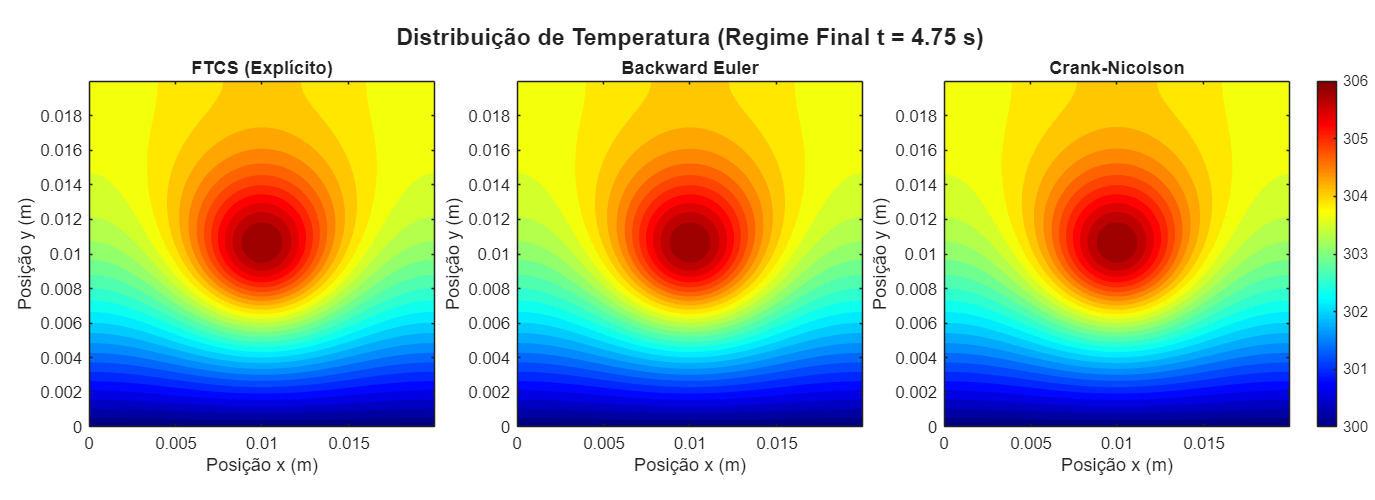

% Descobre a temperatura mínima e máxima global entre os 3 métodos
Tmin = min([min(Temp_ftcs(:)), min(Temp_btcs(:)), min(Temp_cn(:))]);
Tmax = max([max(Temp_ftcs(:)), max(Temp_btcs(:)), max(Temp_cn(:))]);

% Cria a janela do Gráfico
figure('Name', '4. Mapa de Calor Comparativo', 'Position', [100, 200, 1100, 400]);

t = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

% --- Gráfico 1: FTCS ---
nexttile;
contourf(X, Y, Temp_ftcs, 30, 'LineColor', 'none');
colormap(jet);
clim([Tmin Tmax]);
title('FTCS (Explícito)');
xlabel('Posição x (m)'); ylabel('Posição y (m)');
axis equal; tightval = axis; axis(tightval);

% --- Gráfico 2: Backward Euler ---
nexttile;
contourf(X, Y, Temp_btcs, 30, 'LineColor', 'none');
colormap(jet);
clim([Tmin Tmax]);
title('Backward Euler');
xlabel('Posição x (m)'); ylabel('Posição y (m)');
axis equal; tightval = axis; axis(tightval);

% --- Gráfico 3: Crank-Nicolson ---
nexttile;
contourf(X, Y, Temp_cn, 30, 'LineColor', 'none');
colormap(jet);
clim([Tmin Tmax]);
title('Crank-Nicolson');
xlabel('Posição x (m)'); ylabel('Posição y (m)');
axis equal; tightval = axis; axis(tightval);

% --- Barra de Cores Global ---
cb = colorbar;
cb.Layout.Tile = 'east'; 

% Adiciona o título geral ao layout
title(t, 'Distribuição de Temperatura (Regime Final t = 4.75 s)', 'FontSize', 14, 'FontWeight', 'bold');

# Superfície 3D

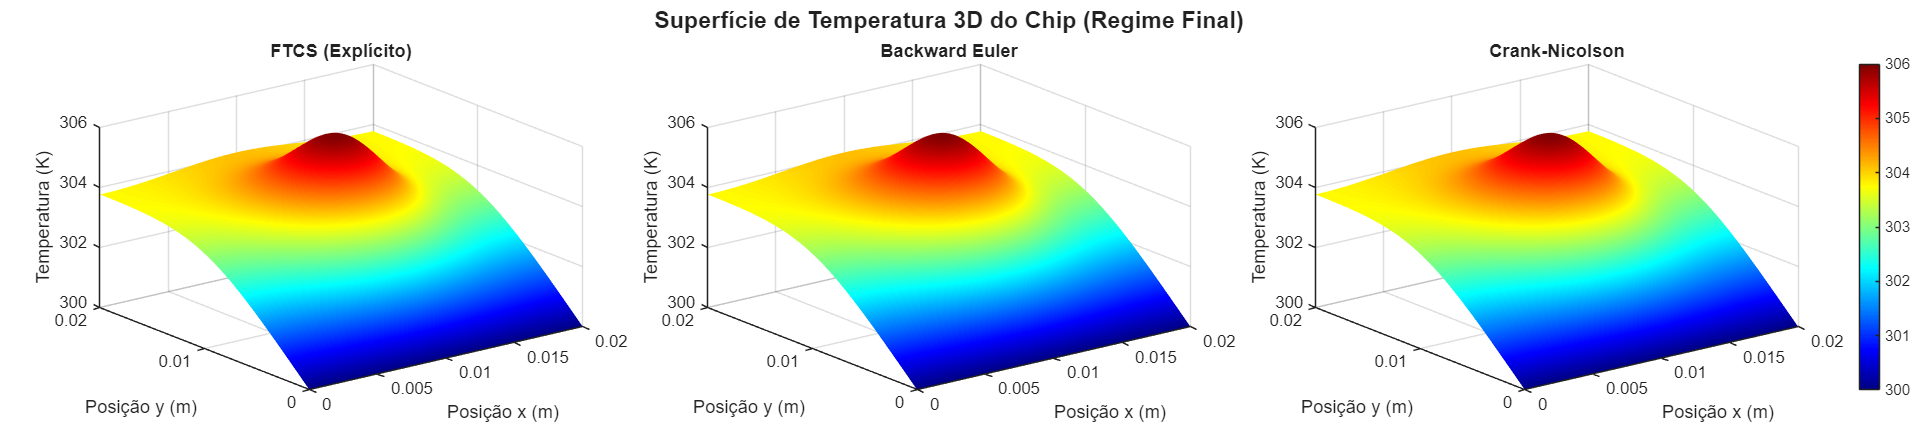

% Descobre a temperatura mínima e máxima global para travar o eixo Z e as cores
Tmin = min([min(Temp_ftcs(:)), min(Temp_btcs(:)), min(Temp_cn(:))]);
Tmax = max([max(Temp_ftcs(:)), max(Temp_btcs(:)), max(Temp_cn(:))]);

% Cria a janela do Gráfico
figure('Name', '2. Superfície 3D', 'Position', [50, 150, 1800, 400]);

% Usa o 'tiledlayout' para organizar lado a lado sem espremer os gráficos
t3d = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

% --- Gráfico 1: FTCS ---
nexttile;
surf(X, Y, Temp_ftcs);
shading interp;
colormap(jet);
clim([Tmin Tmax]);  % Trava a cor
zlim([Tmin Tmax]);   % Trava a altura 3D
xlabel('Posição x (m)');
ylabel('Posição y (m)');
zlabel('Temperatura (K)');
title('FTCS (Explícito)');

% --- Gráfico 2: Backward Euler ---
nexttile;
surf(X, Y, Temp_btcs);
shading interp;
colormap(jet);
clim([Tmin Tmax]);  
zlim([Tmin Tmax]);   
xlabel('Posição x (m)');
ylabel('Posição y (m)');
zlabel('Temperatura (K)');
title('Backward Euler');

% --- Gráfico 3: Crank-Nicolson ---
nexttile;
surf(X, Y, Temp_cn);
shading interp;
colormap(jet);
clim([Tmin Tmax]);  
zlim([Tmin Tmax]);   
xlabel('Posição x (m)');
ylabel('Posição y (m)');
zlabel('Temperatura (K)');
title('Crank-Nicolson');

% --- Barra de Cores Global ---
cb3d = colorbar;
cb3d.Layout.Tile = 'east';

% Título central da janela
title(t3d, 'Superfície de Temperatura 3D do Chip (Regime Final)', 'FontSize', 14, 'FontWeight', 'bold');

# Série temporal do pico máximo

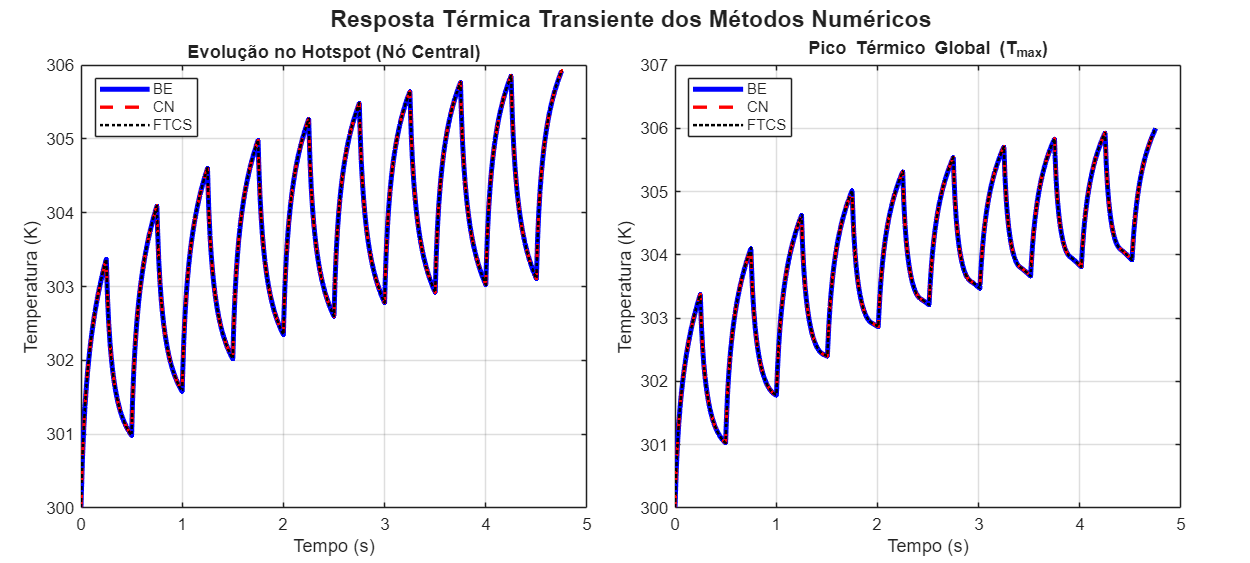

figure('Name', 'Transiente Completo', 'Position', [100, 100, 1000, 450]);
t_layout_trans = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

% Extraindo os tempos e temperaturas
t_ftcs = serie_ftcs(:, 1);   
T_centro_ftcs = serie_ftcs(:, 2);   T_max_ftcs = serie_ftcs(:, 3);

t_be = serie_btcs(:, 1);   
T_centro_be = serie_btcs(:, 2);     T_max_be = serie_btcs(:, 3);

t_cn = serie_cn(:, 1);     
T_centro_cn = serie_cn(:, 2);       T_max_cn = serie_cn(:, 3);

% --- Painel 1: T_centro(t) ---
nexttile;
plot(t_be, T_centro_be, 'b-', 'LineWidth', 3); hold on;
plot(t_cn, T_centro_cn, 'r--', 'LineWidth', 2);
plot(t_ftcs, T_centro_ftcs, 'k:', 'LineWidth', 1.5);
title('Evolução no Hotspot (Nó Central)');
xlabel('Tempo (s)'); ylabel('Temperatura (K)'); 
legend('BE','CN','FTCS', 'Location', 'northwest'); 
grid on;

% --- Painel 2: T_max(t) ---
nexttile;
plot(t_be, T_max_be, 'b-', 'LineWidth', 3); hold on;
plot(t_cn, T_max_cn, 'r--', 'LineWidth', 2);
plot(t_ftcs, T_max_ftcs, 'k:', 'LineWidth', 1.5);
title('Pico Térmico Global (T_{max})');
xlabel('Tempo (s)'); ylabel('Temperatura (K)'); 
legend('BE','CN','FTCS', 'Location', 'northwest'); 
grid on;

title(t_layout_trans, 'Resposta Térmica Transiente dos Métodos Numéricos', 'FontSize', 14, 'FontWeight', 'bold');

# Gráficos de Perfil

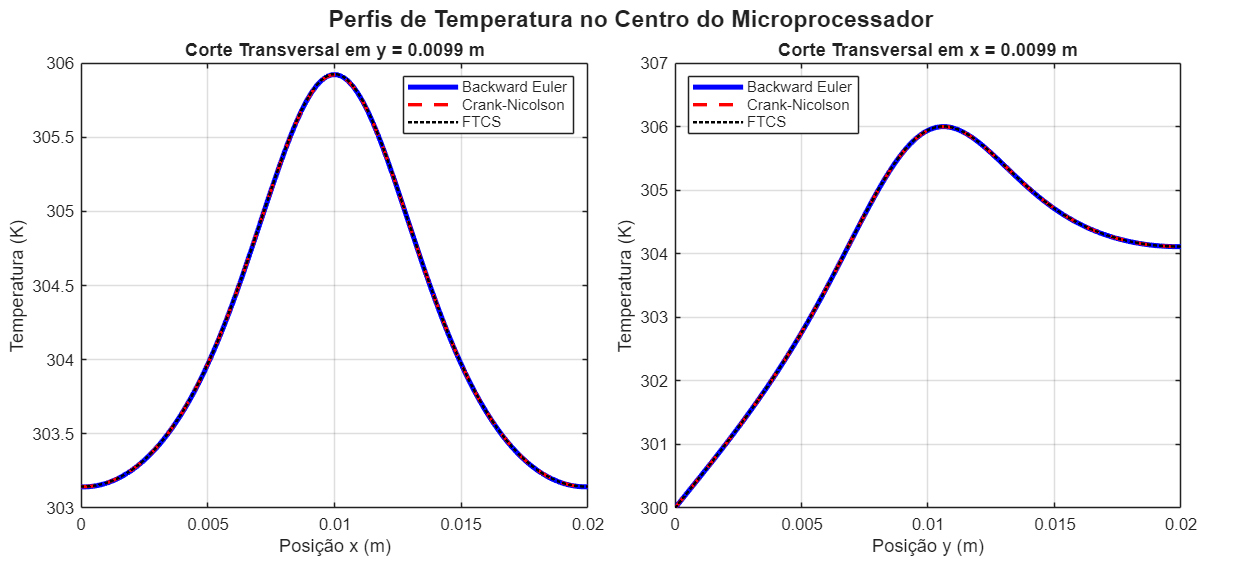

% Descobre automaticamente os índices do centro da malha
meio_x = round(Nx / 2);
meio_y = round(Ny / 2);

% 2. Cria a janela do Gráfico
figure('Name', '4. Perfis Transversais Comparativos', 'Position', [150, 200, 1000, 450]);
t = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

% --- Gráfico 1: Corte ao longo do Eixo X (Mantendo Y fixo no centro) ---
nexttile;
plot(X(:, meio_y), Temp_btcs(:, meio_y), 'b-', 'LineWidth', 3); hold on;
plot(X(:, meio_y), Temp_cn(:, meio_y),   'r--', 'LineWidth', 2);
plot(X(:, meio_y), Temp_ftcs(:, meio_y), 'k:', 'LineWidth', 1.5);

title(sprintf('Corte Transversal em y = %.4f m', Y(1, meio_y)));
xlabel('Posição x (m)');
ylabel('Temperatura (K)');
legend('Backward Euler', 'Crank-Nicolson', 'FTCS', 'Location', 'northeast');
grid on;

% --- Gráfico 2: Corte ao longo do Eixo Y (Mantendo X fixo no centro) ---
nexttile;
plot(Y(meio_x, :), Temp_btcs(meio_x, :), 'b-', 'LineWidth', 3); hold on;
plot(Y(meio_x, :), Temp_cn(meio_x, :),   'r--', 'LineWidth', 2);
plot(Y(meio_x, :), Temp_ftcs(meio_x, :), 'k:', 'LineWidth', 1.5);

title(sprintf('Corte Transversal em x = %.4f m', X(meio_x, 1)));
xlabel('Posição y (m)');
ylabel('Temperatura (K)');
legend('Backward Euler', 'Crank-Nicolson', 'FTCS', 'Location', 'northwest');
grid on;

% Adiciona um título geral para a janela inteira
title(t, 'Perfis de Temperatura no Centro do Microprocessador', 'FontSize', 14, 'FontWeight', 'bold');

# Análise da convergência espacial

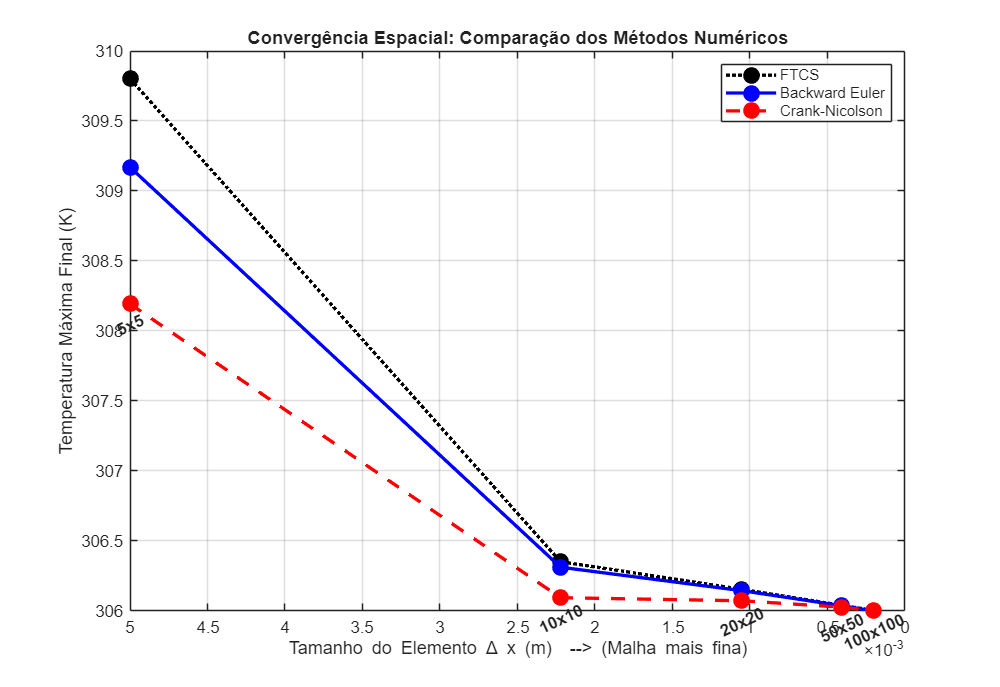

[N_nos_ftcs, idx_ftcs] = sort(conv_ftcs(:, 1));
dx_ftcs = conv_ftcs(idx_ftcs, 2); 
T_ftcs  = conv_ftcs(idx_ftcs, 3);

[N_nos_btcs, idx_btcs] = sort(conv_btcs(:, 1));
dx_btcs = conv_btcs(idx_btcs, 2); 
T_btcs  = conv_btcs(idx_btcs, 3);

[N_nos_cn, idx_cn] = sort(conv_cn(:, 1));
dx_cn = conv_cn(idx_cn, 2); 
T_cn  = conv_cn(idx_cn, 3);

figure('Name', 'Estudo de Convergencia Global', 'Position', [150, 150, 800, 550]);

plot(dx_ftcs, T_ftcs, ':ko', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'k'); hold on;
plot(dx_btcs, T_btcs, '-bo', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
plot(dx_cn,   T_cn,   '--ro', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r');

set(gca, 'XDir', 'reverse'); 

title('Convergência Espacial: Comparação dos Métodos Numéricos');
xlabel('Tamanho do Elemento \Delta x (m)  --> (Malha mais fina)');
ylabel('Temperatura Máxima Final (K)');

legend('FTCS', 'Backward Euler', 'Crank-Nicolson', 'Location', 'northeast');
grid on;

for i = 1:length(N_nos_cn)
    texto = sprintf('%dx%d', N_nos_cn(i), N_nos_cn(i));
    text(dx_cn(i), T_cn(i) - 0.15, texto, ...
        'HorizontalAlignment', 'center', 'Rotation', 25, 'FontSize', 10, 'FontWeight', 'bold');
end

# Estudo de estabilidade

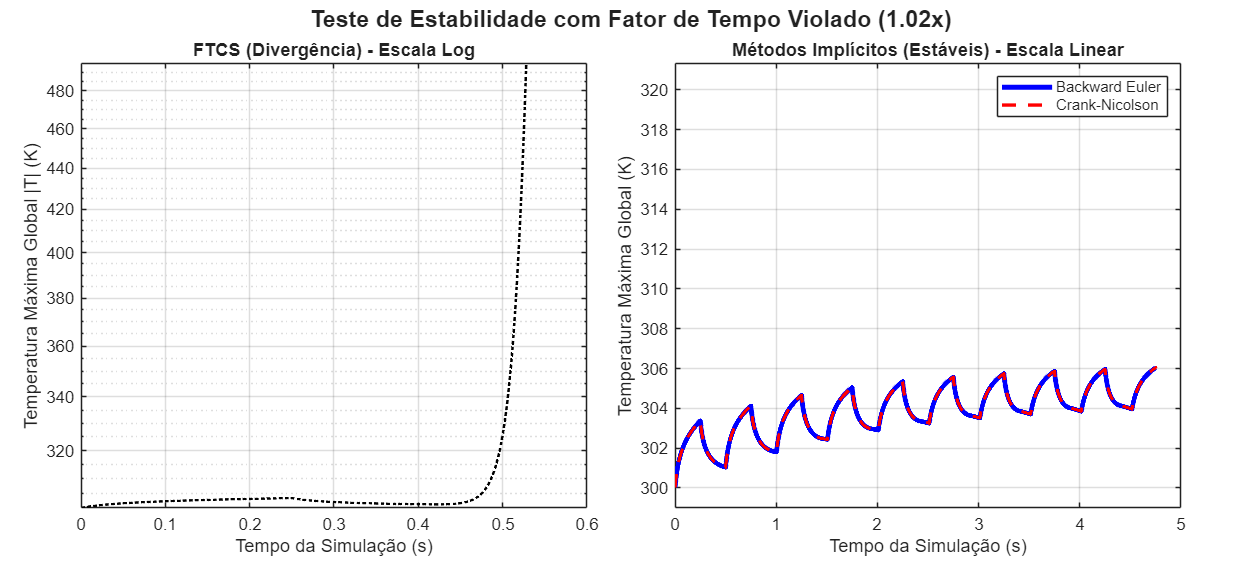

figure('Name', 'Analise de Estabilidade', 'Position', [200, 200, 1000, 450]);

% Descobre o limite superior dos métodos estáveis
T_max_estavel = max([max(stab_btcs(:,3)), max(stab_cn(:,3))]);
limite_y_linear = [299, T_max_estavel * 1.05];

t_layout_stab = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

% --- Painel 1: FTCS (Escala Logarítmica mostrando a divergência) ---
nexttile;
% Usamos abs() pois a instabilidade gera valores negativos absurdos
semilogy(stab_ftcs(:,1), abs(stab_ftcs(:,3)), 'k:', 'LineWidth', 1.5);
title('FTCS (Divergência) - Escala Log');
xlabel('Tempo da Simulação (s)');
ylabel('Temperatura Máxima Global |T| (K)');
grid on;

% --- Painel 2: Métodos Implícitos (Escala Linear) ---
nexttile;
plot(stab_btcs(:,1), stab_btcs(:,3), 'b-', 'LineWidth', 3); hold on;
plot(stab_cn(:,1),   stab_cn(:,3), 'r--', 'LineWidth', 2);
title('Métodos Implícitos (Estáveis) - Escala Linear');
xlabel('Tempo da Simulação (s)');
ylabel('Temperatura Máxima Global (K)');
ylim(limite_y_linear);
legend('Backward Euler', 'Crank-Nicolson', 'Location', 'northeast');
grid on;

title(t_layout_stab, 'Teste de Estabilidade com Fator de Tempo Violado (1.02x)', 'FontSize', 14, 'FontWeight', 'bold');

# Campos de temperatura em instantes selecionados

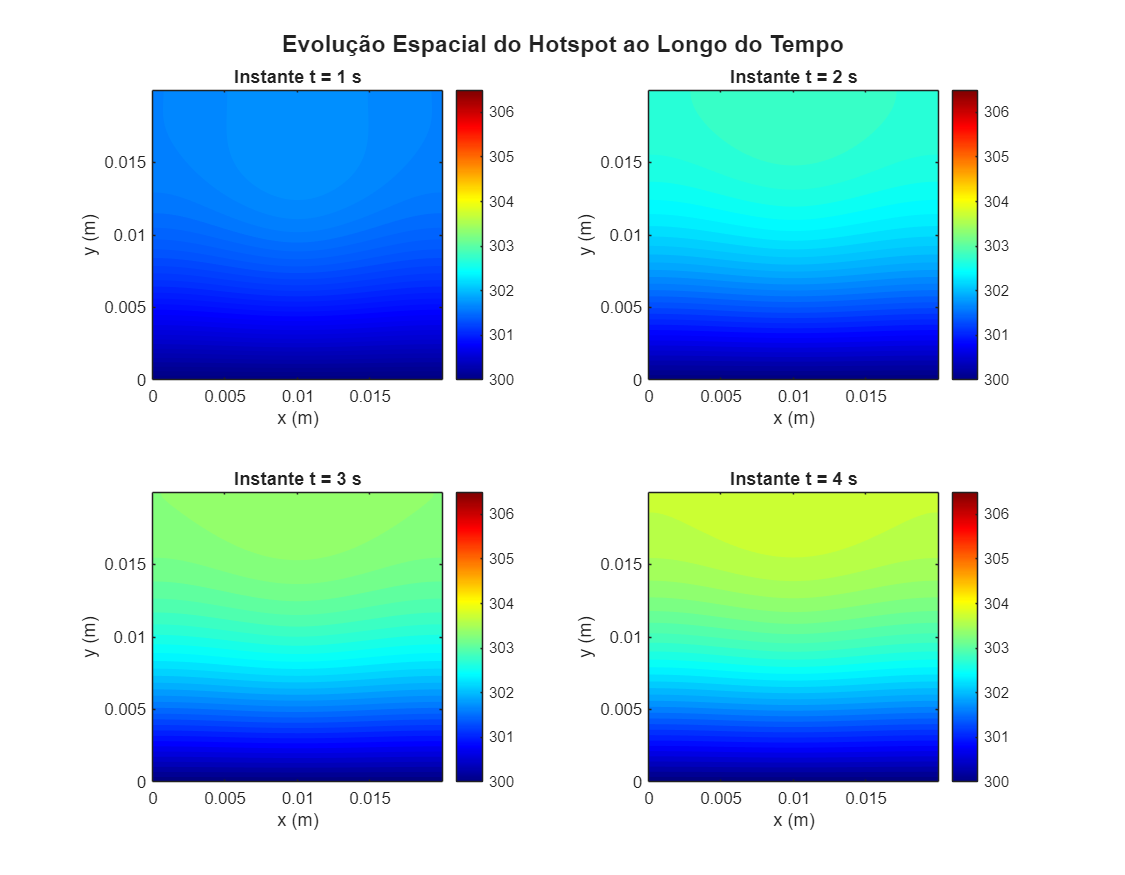

tempos = [1, 2, 3, 4];

figure('Name', 'Evolução Temporal (Snapshots)', 'Position', [100, 100, 900, 700]);

% Descobre a escala global de temperatura para manter as cores justas
T_min_global = 300;
T_max_global = 306.5; 

for k = 1:length(tempos)
    % Lê o arquivo correspondente da pasta de resultados
    filename = sprintf('snap_cn_%ds.dat', tempos(k));
    data = load(filename);
    
    x = data(:,1);
    y = data(:,2);
    T = data(:,3);

    % Automação da Malha
    Nx = length(unique(x));
    Ny = length(unique(y));
    
    X = reshape(x, Ny, Nx)';
    Y = reshape(y, Ny, Nx)';
    Temp = reshape(T, Ny, Nx)';

    % Cria o painel 2x2
    subplot(2, 2, k);
    contourf(X, Y, Temp, 30, 'LineColor', 'none');
    colormap(jet);
    
    % Trava a escala de cores para todos os gráficos serem comparáveis
    clim([T_min_global T_max_global]); 
    colorbar;
    
    title(sprintf('Instante t = %d s', tempos(k)));
    xlabel('x (m)');
    ylabel('y (m)');
    axis equal; tightval = axis; axis(tightval);
end

% Título central da janela
sgtitle('Evolução Espacial do Hotspot ao Longo do Tempo', 'FontSize', 14, 'FontWeight', 'bold');

# Gráfico de convergência de erro (Erro vs dx)

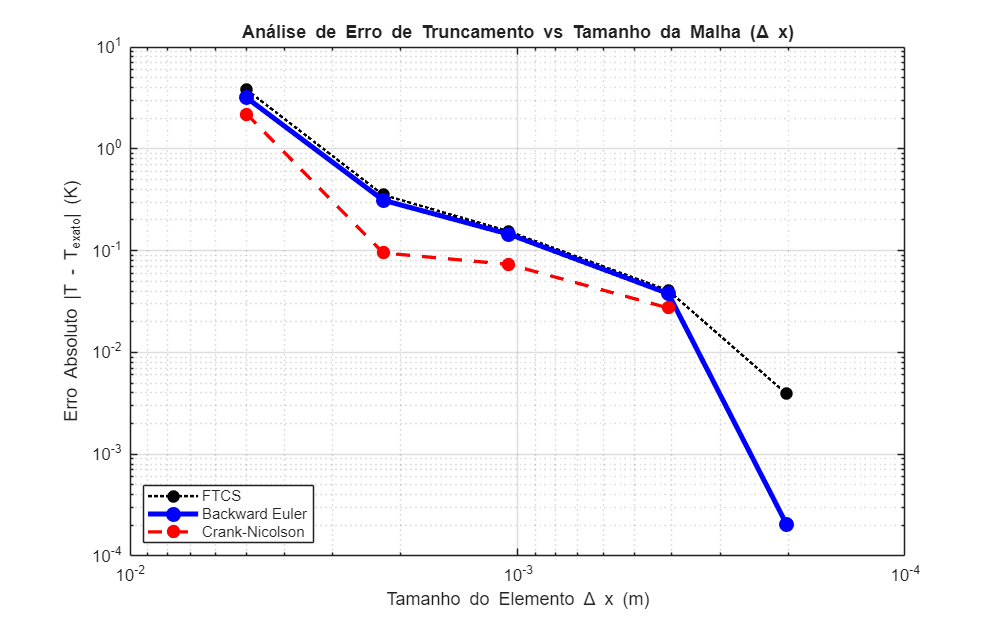

T_exato = T_cn(end); 

% Calcula o Erro Absoluto para cada método
erro_ftcs = abs(T_ftcs - T_exato);
erro_btcs = abs(T_btcs - T_exato);
erro_cn   = abs(T_cn - T_exato);

figure('Name', 'Erro vs Delta x', 'Position', [200, 200, 800, 500]);

% Usa loglog (Escala logarítmica em ambos os eixos)
loglog(dx_ftcs, erro_ftcs, 'k:o', 'LineWidth', 1.5, 'MarkerFaceColor', 'k'); hold on;
loglog(dx_btcs, erro_btcs, 'b-o', 'LineWidth', 3, 'MarkerFaceColor', 'b');
loglog(dx_cn(1:end-1), erro_cn(1:end-1), 'r--o', 'LineWidth', 2, 'MarkerFaceColor', 'r'); % Oculta o último ponto do CN pois o erro é zero (log(0) não existe)

set(gca, 'XDir', 'reverse'); % Malha mais fina para a direita

title('Análise de Erro de Truncamento vs Tamanho da Malha (\Delta x)');
xlabel('Tamanho do Elemento \Delta x (m)');
ylabel('Erro Absoluto |T - T_{exato}| (K)');
legend('FTCS', 'Backward Euler', 'Crank-Nicolson', 'Location', 'southwest');
grid on;

# Consumo de tempo de CPU

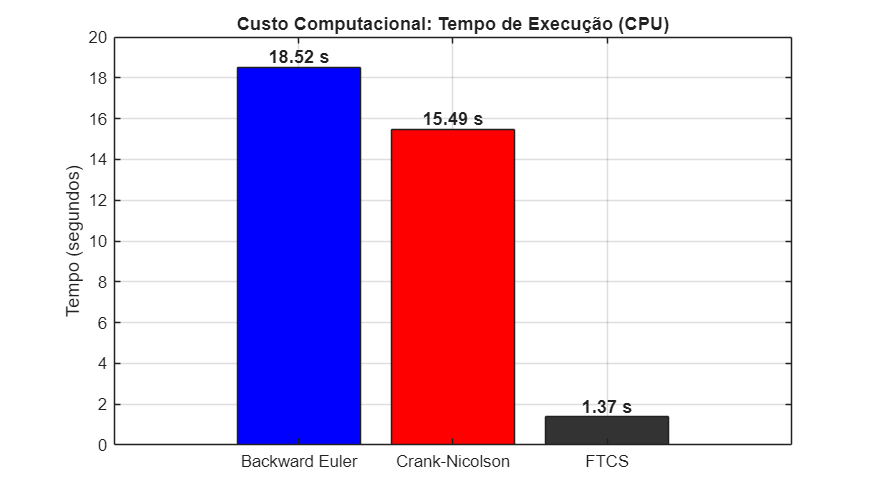

% Extrai o tempo de CPU (Coluna 5)
tempos_cpu = [m_btcs(5), m_cn(5), m_ftcs(5)];
nomes_metodos = {'Backward Euler', 'Crank-Nicolson', 'FTCS'};

figure('Name', 'Consumo de Tempo (CPU)', 'Position', [250, 250, 700, 400]);

% Cria o gráfico de barras
b = bar(tempos_cpu, 'FaceColor', 'flat');

% Aplica a nossa identidade visual nas barras
b.CData(1,:) = [0 0 1];      % Azul para Backward Euler
b.CData(2,:) = [1 0 0];      % Vermelho para Crank-Nicolson
b.CData(3,:) = [0.2 0.2 0.2];% Cinza escuro/Preto para FTCS

set(gca, 'xticklabel', nomes_metodos);
title('Custo Computacional: Tempo de Execução (CPU)');
ylabel('Tempo (segundos)');
grid on;

% Adiciona os valores em texto em cima de cada barra
for i = 1:length(tempos_cpu)
    text(i, tempos_cpu(i), sprintf('%.2f s', tempos_cpu(i)), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
        'FontSize', 11, 'FontWeight', 'bold');
end

# Tabela de dados

esquemas   = {'FTCS'; 'Backward Euler'; 'Crank-Nicolson'};

% Extraindo TODOS os 10 parâmetros gerados
Nx         = [m_ftcs(1); m_btcs(1); m_cn(1)];
dx         = [m_ftcs(2); m_btcs(2); m_cn(2)];
dt         = [m_ftcs(3); m_btcs(3); m_cn(3)];
rx         = [m_ftcs(4); m_btcs(4); m_cn(4)];
tempo_cpu  = [m_ftcs(5); m_btcs(5); m_cn(5)];
T_max      = [m_ftcs(6); m_btcs(6); m_cn(6)];
t_limiar   = [m_ftcs(7); m_btcs(7); m_cn(7)];
iter_passo = [m_ftcs(8); m_btcs(8); m_cn(8)];
res_max    = [m_ftcs(9); m_btcs(9); m_cn(9)];
erro_l2    = [m_ftcs(10); m_btcs(10); m_cn(10)];

% Trata o caso do limiar de tempo (se for < 0, não atingiu 302 K)
t_limiar_str = cell(3,1);
res_max_str  = cell(3,1);
erro_l2_str  = cell(3,1);

for i = 1:3
    % Formatação do Limiar Térmico
    if t_limiar(i) < 0
        t_limiar_str{i} = 'Não Atingido';
    else
        t_limiar_str{i} = sprintf('%.3f s', t_limiar(i));
    end
    
    % Formatação dos Resíduos (Notação Científica)
    % O índice 1 é o FTCS, que é explícito (não tem iteração nem resíduo)
    if i == 1 
        res_max_str{i} = '-';
        erro_l2_str{i} = '-';
    else
        res_max_str{i} = sprintf('%.2e', res_max(i));
        erro_l2_str{i} = sprintf('%.2e', erro_l2(i));
    end
end

% Monta a Tabela Completa
data = table(esquemas, Nx, dx, dt, rx, T_max, tempo_cpu, iter_passo, res_max_str, erro_l2_str, t_limiar_str, ...
    'VariableNames', {'Esquema', 'Nx', 'dx', 'dt', 'rx', 'T_max_K', 'CPU_s', 'Iter_por_Passo', 'Residuo_Max', 'Erro_L2', 'Tempo_Limiar'});

% Exibe a tabela
disp('--- TABELA COMPLETA DE RESULTADOS ---');

--- TABELA COMPLETA DE RESULTADOS ---


disp(data);

         Esquema          Nx         dx            dt         rx     T_max_K    CPU_s     Iter_por_Passo    Residuo_Max       Erro_L2       Tempo_Limiar
    __________________    ___    __________    __________    ____    _______    ______    ______________    ____________    ____________    ____________

    {'FTCS'          }    100    0.00020202    0.00011094    0.25      306      1.3728             1        {'-'       }    {'-'       }    {'0.076 s'} 
    {'Backward Euler'}    100    0.00020202    0.00011094    0.25      306      18.523        5.0413        {'7.33e-06'}    {'3.81e-06'}    {'0.076 s'} 
    {'Crank-N